%ER_7.0 calculations and outputs

%Aero related
drag_coeff     = 0.584;
front_area     = 0.7590;

%VD related
CG_height              = 310;
front_axle             = 800;
rear_axle              = 775;
roll_resist            = 0.02;
tire_b                 = 10;
tire_c                 = 1.9;
tire_d                 = 1 ;
tire_e                 = 0.97;
tire_dia               = 18;
tire_inertia           = 0.001;
vehicle_mass           = 220;
rider_mass             = 60;

%Powertrain related
gear_ratio             = 2.267;

%To run the simulink file
sim('ER_7.slx')

%To Extract values from the simulation
Speed = Speed.signals.values;
Torque = Torque.signals.values;
InstantaneousPower = InstantaneousPower.signals.values;
Time = tout;

%Max speed, torque and Time of simulation
% Ms = max(Speed)
% Mt = max(Torque)
TotalPower_used = sum(InstantaneousPower)

TotalPower_used = 640.5725

Simul_time = max(Time)

Simul_time = 100



%plotting values

[Ms, indexMax] = max(Speed)

Ms = 79.7574

indexMax = 132

Timax = Time(indexMax)

Timax = 100

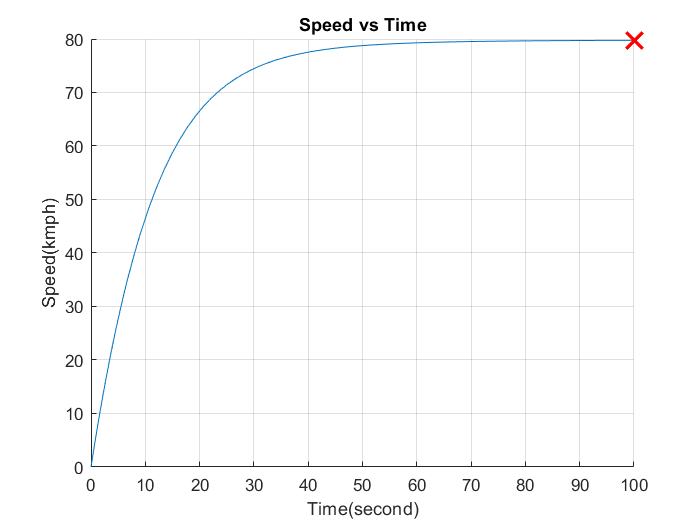


figure 
hold on
plot(Time,Speed)
plot(Timax,Ms,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Speed(kmph)')
grid on
title('Speed vs Time')


[Mt, indexMax] = max(Torque)

Mt = 129.2349

indexMax = 42

Timax = Time(indexMax)

Timax = 0.0074

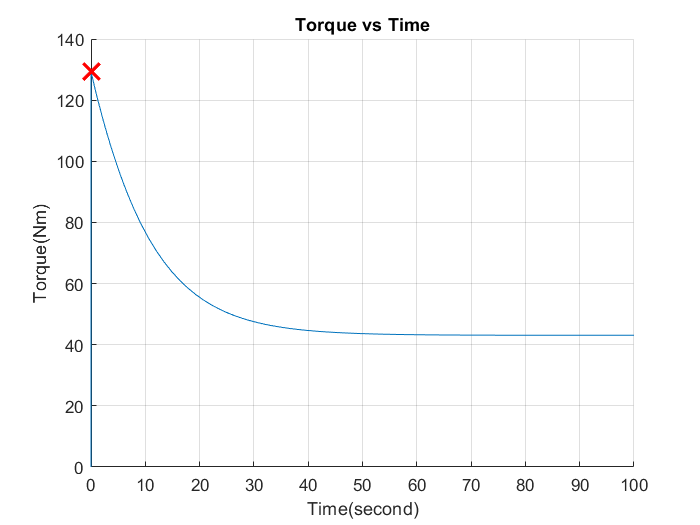


figure
hold on
plot(Time,Torque)
plot(Timax,Mt,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Time')


[Mt , indexMax] = max(Torque)

Mt = 129.2349

indexMax = 42

Smax = Speed(indexMax)

Smax = 0.0431

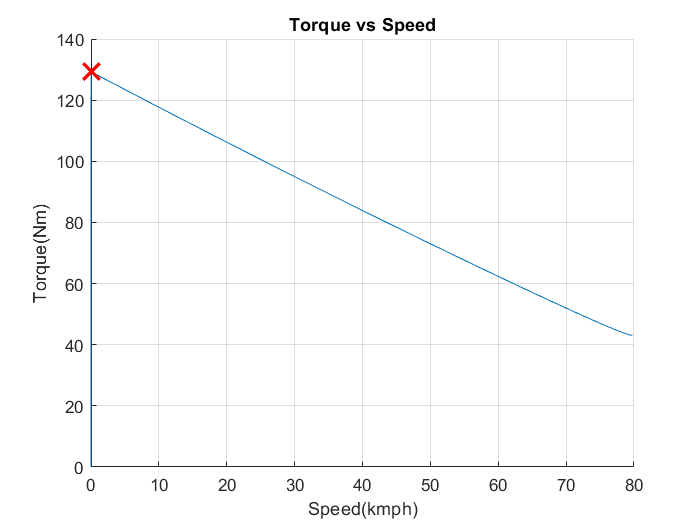


figure
hold on
plot(Speed,Torque)
plot(Smax ,Mt ,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Speed(kmph)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Speed')